# Mass damper spring system

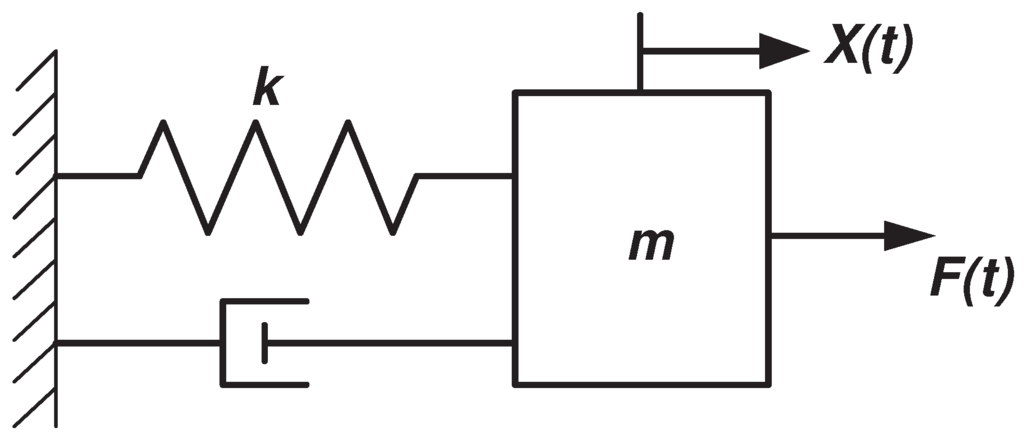

We will consider the following system. This system has the following state space representation:


$$\pmatrix{\dot{x} \cr \ddot{x}} = 
\pmatrix{0 & 1 \cr \frac{-k}{M} & \frac{-f_v}{M}}
\pmatrix{x \cr \dot{x}} +
\pmatrix{0 \cr \frac{1}{M}} u$$


k = 1;
M = 1;
f = 1;
A = [0 1 ; -k/M -f/M];
B = [0 ; 1/M];
C = [1 0 ; 0 1];
D = [];
sys_mds_c = ss(A,B,C,D);

## Impulse response

For this example we will consider data generated by the impulse response of this system.

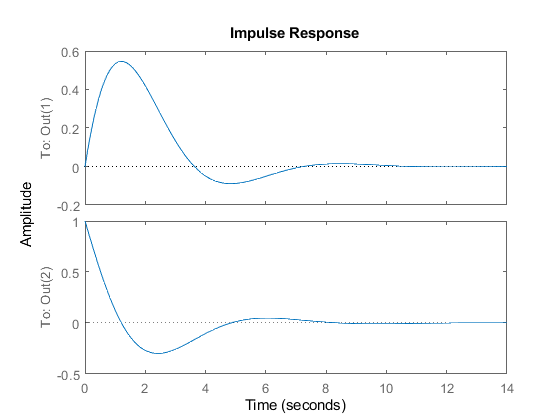

impulse(sys_mds_c)

[y_impulse, t_impulse, x_impulse] = impulse(sys_mds_c);

### Defining the data

We will first consider all `150` datapoints generated. Since we are considering the impulse responce we have that our input vector is equal to `[1 0 0 ...]` and is of size `1x149`.

U_impulse = zeros(1,149);
U_impulse(1) = 1;
X_impulse = x_impulse';

### System identification

We can check if the data is informative for system identification by using `[bool, A, B] = isIdentifiable(X, U)`. For this to be the case we need that the data is full rank, i.e.:


$$rank \pmatrix{X_- \cr U_-} = n + m$$


Since we use the impulse function we know that the first collumn will be linearly independant with respect to all other columns. Hence we only need 2 other columns to be linearly independant. From this we can see that the use of 150 data points is a bit eccesive, hence we also consider some cases below where we reduce the amount of data points.

[bool, A_impulse, B_impulse] = isIdentifiable(X_impulse, U_impulse)

bool = logical
   1


A_impulse =     0.9959    0.0879
   -0.0879    0.9080


B_impulse = 	1.0e+-16 *

    0.3282
   -0.3077


We will use the received A and B matrix to verify the data.

#### Verifying results

We can check the validity of the results by comparing them against the continuous time version of the system. To get the continuous time system we use the [`sysc = d2c(sysd)`](https://nl.mathworks.com/help/control/ref/d2c.html#d122e34030) function provided by matlab. (We can find the timestep of the data by inspecting the `t` array that was returned by the impuls function)

sys_impulse_d = ss(A_impulse, B_impulse, C, D, t_impulse(2));
sys_impulse_c = d2c(sys_impulse_d)

sys_impulse_c =
 
  A = 
              x1         x2
   x1  2.034e-15          1
   x2         -1         -1
 
  B = 
               u1
   x1   3.717e-16
   x2  -3.328e-16
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



As we can see we do get an accurate `A` (up to machine presision), but the `B` is off. *This is probably due to the use of the impulse responce which is practically 0, since if *$U_- = [0 \dots 0]
$ *we are not able to infere anything about the *`B`* matrix. We will verify this by repeating these steps for the step function, which will result in *$U_- = [1 \dots 1]$.

## Step response

As noted above, we will repeat the calculations made for the step response to see if we can infere the `B` matrix.

### Defining data

We will start by considering all 150 data points generated by the step function. We will see lateron that this is ecsessive and that we can use less points for the same result.

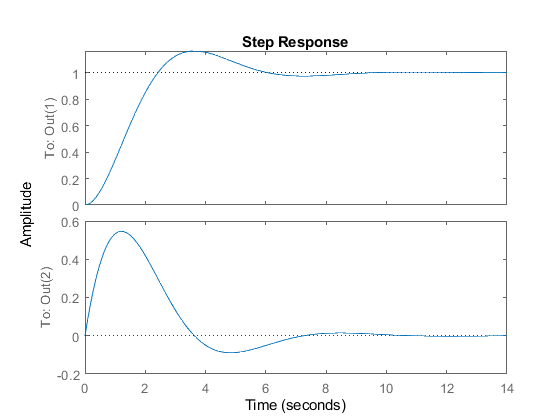

step(sys_mds_c)

[y_step, t_step, x_step] = step(sys_mds_c);
U_step = ones(1,149);
X_step = x_step.';

### System identification

We will again use the `[bool, A, B] = isIdentifiable(X, U) function to see if the data is informative for system identification.`

[bool, A_step, B_step] = isIdentifiable(X_step, U_step)

bool = logical
   1


A_step =     0.9959    0.0879
   -0.0879    0.9080


B_step =     0.0041
    0.0879


As we can see the data is indeed informative for system identification.

#### Verifying results

We will once again check the validity of the data by first converting the system back to a continuous time system using the [`sysc = d2c(sysd)`](https://nl.mathworks.com/help/control/ref/d2c.html#d122e34030) function provided by matlab, using the same timestep as the data, namely `t_step(2)`.

sys_step_d = ss(A_step, B_step, C, D, t_step(2));
sys_step_c = d2c(sys_step_d)

sys_step_c =
 
  A = 
              x1         x2
   x1  4.822e-15          1
   x2         -1         -1
 
  B = 
              u1
   x1  3.466e-15
   x2          1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



As we can see we get the valid `A` and `B` (up to working precision). Thus we can conclude that the impulse response in insufficient for finding the `B` matrix of the system. It is however still informative for identification of the `A` matrix.

## How much data is needed and what is the precision

We will now look at how much data we need for system identification, for this we will check the first `n` entries of the step response data where `n` is from `1` to `10`. We will also use these results to check the consistency of the result based on the amount of data provided.

valid = [];
a11 = [];
a12 = [];
a21 = [];
a22 = [];
b1  = [];
b2  = [];
for idx = 1:10
    X_temp = X_step(:,1:idx+1);
    U_temp = U_step(:,1:idx);
    if isIdentifiable(X_temp, U_temp)
        valid = [valid idx];
        [~, A_temp, B_temp] = isIdentifiable(X_temp, U_temp);
        a11 = [a11 A_temp(1,1)];
        a12 = [a12 A_temp(1,2)];
        a21 = [a21 A_temp(2,1)];
        a22 = [a22 A_temp(2,2)];
        b1  = [b1  B_temp(1)];
        b2  = [b2  B_temp(2)];
    end
end

From this we can inspect the `valid` array and see for how many data points the data is informative for system identification. As we noted earlier, we only needed `3`  linearly independant collumns, which where the 1st, 2nd and 3rd collumn in this case.

disp("How many data points are needed for system identification?:")

How many data points are needed for system identification?:


valid

valid =      3     4     5     6     7     8     9    10


We can also check to see the larges difference between values that we received for the `A` and `B` matrix. As we can see the `A` and `B` are unique up to working precision.

disp("The maximal difference between the returned A and B matrices.")

The maximal difference between the returned A and B matrices.


A_delta = [max(a11)-min(a11) max(a12)-min(a12);
           max(a21)-min(a21) max(a22)-min(a22)]

A_delta = 	1.0e+-13 *

    0.1110    0.0047
    0.1954    0.0144


B_delta = [max(b1)-min(b1);
           max(b2)-min(b2)]

B_delta = 	1.0e+-15 *

    0.0746
    0.4025


## Controllability

In this section we will see if the data is informative for controllability. We can check this using the `bool = isControllable(X)` function.

disp("The data is informative for controllability?");

The data is informative for controllability?


disp(isControllable(X_step));

   1



As we can see the data is informative for controllability. We can verify this by means of the reachability matrix of the actual system.

disp("The system is controllable?");

The system is controllable?


disp(rank([B A*B]) == 2);

   1



## Stabilisability

In this section we will see if the data is informative for stabilizability. We can check if the data is informative for stabilizability by using the function `bool = isStabilisable(X)`.

disp("The data is informative for system stabilisability?");

The data is informative for system stabilisability?


disp(isStabilisable(X_step))

   1



As expected, the data is informative for stabilisability. This is what we would expect since if a system is controllable it should also be stabilisable.

## State feedback

Since our system is controllable, we might want to find a state feedback controller, in this example it is unneccesary since the system is already stable, but lets assume we are not aware of this. To find a full state feedback controller we can use the function `[bool, K, diagnostics] = StateFeedbackYalmip(X, U, tolerance, options)`.

[bool, K, diagnostics] = StateFeedbackYalmip(X_step, U_step);

Since we have that the data is also informative for system identification, we can verify the result.

disp("Is the data informative for state feedback?");

Is the data informative for state feedback?


disp(bool);

   1



disp("The eigenvalues of A+BK are:");

The eigenvalues of A+BK are:


disp(eig(A_step + B_step * K));

   0.9996 + 0.0182i
   0.9996 - 0.0182i



disp("Their magnitude is:");

Their magnitude is:


disp(abs(eig(A_step + B_step * K)));

    0.9998
    0.9998



Thus the provided controller is indeed a stabilizing controller, al be it a slow one. Currently it is not possible to place the poles for the given controller.

## Deadbeat Control

Since our system is controllable, we might want to find a deadbeat controller. A deadbeat controller is a controller that brings the system to a stable state in `1` iterarion. This is done by finding a controller that assigns the eigenvalues of the closed loop system to zero. To do this we will use the function `[bool, K] = isInformDeadbeatControl(X, U)`.

# See problems.txt

[bool, K] = isInformDeadbeatControl(X_step(:,1:5), U_step(:,1:4))

Error using acker (line 31)
System must be single input

Error in isInformDeadbeatControl (line 38)
            H = acker(Xplus*F, -Xplus*G, zeros(1,n));

disp("Is the data informative for deadbeat control?");
disp(bool);
disp("What is the corresponding controller?");
disp(K);
disp("The eigenvalues of the closed loop system are:")
disp(eig(A_step + B_step * K))